# Calculation of Total Harmonic Distortion

## Load Data

load('CurrentDataMatLab2.MAT')

## Define Sampling frequency and fundamental

Fs=50e3;
N=50;

## Calculate Harmonics


[r,harmpow,harmfreq] = thd(VppTestCurrentPhaseA,Fs,N)

r = -30.5075

harmpow =    13.5480
  -19.7420
  -23.7069
  -27.0214
  -27.4917
  -41.3387
  -33.1439
  -47.5467
  -36.1914
  -51.7191


harmfreq = 	1.0e+03 *

    0.0490
    0.0980
    0.1470
    0.1960
    0.2450
    0.2940
    0.3430
    0.3920
    0.4410
    0.4900


## Calculate Percent Harmonic Distortion

percent_thd = 100*(10^(r/20))

percent_thd = 2.9828

## Create a Table of harmonic components with power

T = table(harmfreq,harmpow,'VariableNames',{'Frequency','Power'})

T = 50×2 table
    Frequency     Power 
    _________    _______

         49       13.548
     97.998      -19.742
        147      -23.707
        196      -27.021
        245      -27.492
     293.99      -41.339
        343      -33.144
     391.99      -47.547
        441      -36.191
     489.99      -51.719
     538.99      -38.279
        588      -48.215
     636.99      -41.157
        686      -52.587
     734.99      -46.576
     783.99      -56.309


## Create a THD plot

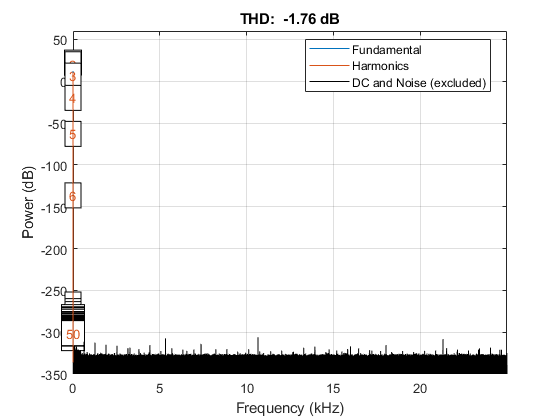

thd(VppTestTimeGenerated,Fs,N);